# **Lab 1**

*Joel Sundin, Pablo Gonzalez Baron*

### 1. Histogram Equalization

We start by creating a histogram of the given image. We then calculate the cumulative sum of the histogram and normalizes this array so that it ranges from 0 to 1. Each pixel value and its corresponding equalized value is then mapped and the output is converted back to uint8.

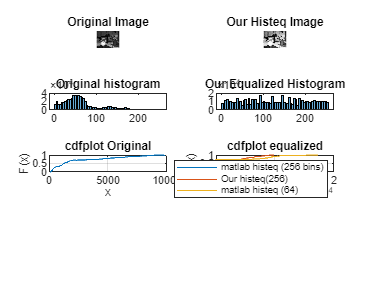

clear;

I = imread("images\greytoys.png");
my_histeq = myhisteq(I);
matlab_histeq_256_bins = histeq(I, 256);
matlab_histeq_64_bins = histeq(I);

figure
subplot(4, 2, 1)
imshow(I)
title('Original Image')

subplot(4, 2, 2)
imshow(my_histeq)
title('Our Histeq Image')

subplot(4, 2, 3)
histogram(I, 64)
title('Original histogram')

subplot(4, 2, 4)
histogram(my_histeq, 64)
title('Our Equalized Histogram')

%Original cdfplot
subplot(4, 2, 5);
cdfplot(imhist(I))
title('cdfplot Original')

%Original cdfplot
subplot(4, 2, 6);
cdfplot(imhist(matlab_histeq_256_bins))
hold on 
cdfplot(imhist(my_histeq))
hold on
cdfplot(imhist(matlab_histeq_64_bins))
legend('matlab histeq (256 bins)', 'Our histeq(256)', 'matlab histeq (64)')
title('cdfplot equalized')
hold off


function histeq = myhisteq(image)
    histogram = myhist(image);
    sum = cumsum(histogram);
    cdf = sum / sum(end);
    levels = 255;

    mapping = round((levels) * cdf);
    out = mapping(double(image) + 1);
    histeq = uint8(out);
end

function histogram = myhist(image)
    [rows, cols] = size(image);
    histogram = zeros(1, 256); % [0, 255]

    for i=1:1:rows
        for j=1:1:cols
            pixel_intensity = image(i, j);
            histogram(pixel_intensity + 1) = histogram(pixel_intensity + 1) + 1;
        end
    end
end

### 4. Multispectral Images

% 4
clear;

load landsat_data.mat
disp('Include in your report the combination which best visualises the urban area, as well as the one that highlights the agricultural area.')

Include in your report the combination which best visualises the urban area, as well as the one that highlights the agricultural area.


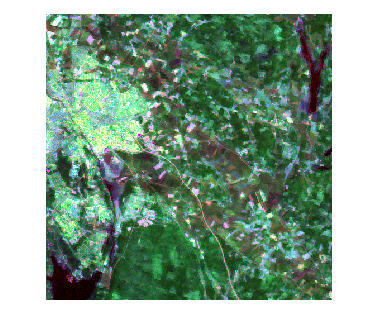

figure
imshow(landsat_data(:,:,[1,6,7]));

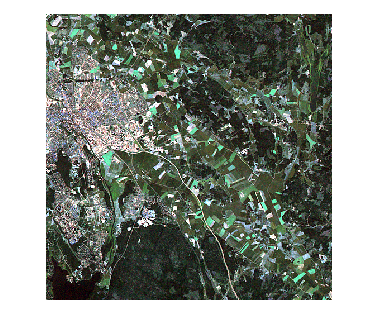

figure
imshow(landsat_data(:,:,[1,2,3]))

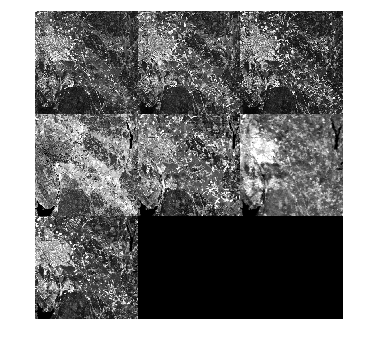

figure
montage(landsat_data)
hold off

### 5. Pixel Neighbourhoods - Mean Filter

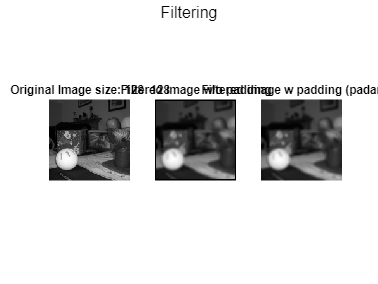

clear;

I = imread("images\toysflash.png");

I = rgb2gray(I);
I = im2double(I);
[orig_rows, orig_cols] = size(I);

%The image is cropped to a square according to the smallest axis
min_dim = min(orig_rows, orig_cols);
row_start = floor((orig_rows - min_dim) / 2) + 1;
col_start = floor((orig_cols - min_dim) / 2) + 1;

I_cropped = I(row_start:row_start + min_dim - 1, col_start:col_start + min_dim - 1);
I_resized = imresize(I_cropped, [128, 128]);

%filtering
w_size = 5;
filtered_no_padding = mean_filter_no_padding(I_resized, w_size);
filtered_padding = mean_filter_w_padding(I_resized, w_size);

figure
sgtitle('Filtering')
subplot(1, 3, 1)
imshow(I_resized)
title(['Original Image size: ', num2str(size(I_resized))])
subplot(1, 3, 2)
imshow(filtered_no_padding)
title('Filtered image w/o padding')
subplot(1, 3, 3)
imshow(filtered_padding)
title('Filtered image w padding (padarray)')

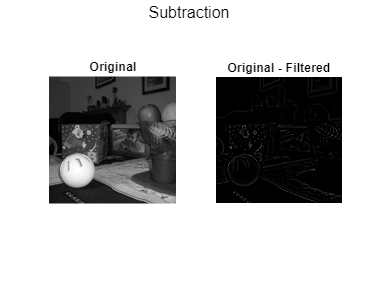


%subtraction
figure
sgtitle('Subtraction')
subplot(1, 2, 1)
imshow(I_resized)
title('Original')
subplot(1,2,2)
imshow(I_resized - filtered_padding)
title('Original - Filtered')



function I_filtered = mean_filter_no_padding(I, w_size)
    w_size = round(w_size);
    center = floor(w_size / 2);
    [rows, cols] = size(I);
    I_filtered = zeros(rows, cols);
    for i = 1:rows-w_size+1
        for j = 1:cols-w_size+1
            window = I(i:i+w_size-1, j:j+w_size-1);
            window_mean = sum(window, 'all') / w_size^2;
            I_filtered(i+center, j+center) = window_mean;
        end
    end
end

function I_filtered = mean_filter_w_padding(I, w_size)
    [rows, cols] = size(I);
    padding = floor(w_size / 2);
    I_filtered = zeros(rows, cols);
    I_padded = padarray(I, [padding, padding], 'replicate', 'both');
    for i = 1:rows
        for j = 1:cols
            window = I_padded(i:i+w_size-1, j:j+w_size-1);
            window_mean = sum(window, 'all') / w_size^2;
            I_filtered(i, j) = window_mean;
        end
    end
end

### 6. Preprocessing and Segmentation

clear;

I = imread("images\hand2BW.png");
[counts, x] = imhist(I,256)

counts =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


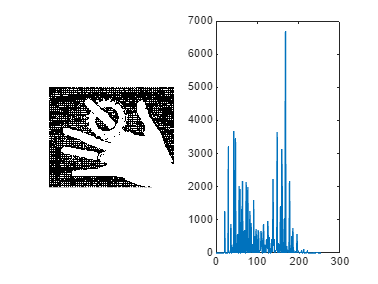

plot(x,counts);

T = otsuthresh(counts)

T = 0.4196

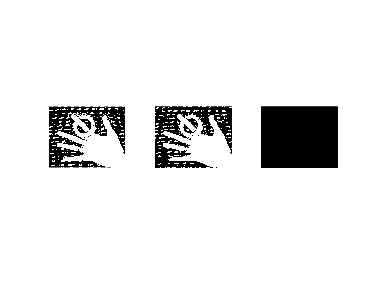

threshold = graythresh(I);
I_otsu_bin = imbinarize(I, T);
I_otsu_bin2 = imbinarize(I, threshold);
figure
subplot(1,3,1)
imshow(I_otsu_bin2)
subplot(1,3,2)
imshow(I_otsu_bin)
subplot(1,3,3)
imshow(I_otsu_bin2 - I_otsu_bin)

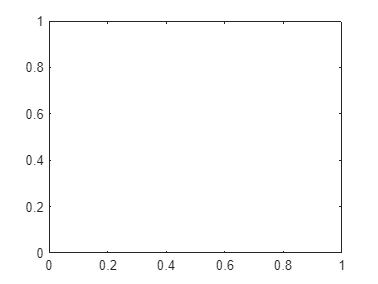

clear;
cla;


I = imread("images\hand2BW.png")

I = 243×303 uint8 matrix
    56    21    21    85    62    43    21    21    36    36    21    21    73   115    91    36    30    47    94    77    21    47    91    85    43    21    21   122    77    47    30    85   126   103    64    43   159   129    77    30    85   138   138    64    56   194   208   123    62    47
    45    61    73    64    36    49    30    49    39    43    42    35    58    73    62    30    49    43    94    64    43    56    64    47    36    21    21    47    47    43    21    56    64    43    47    30    73    47    47    30    21    77    62    47    43    99    99    73    21    21
    56    91    82    43    21    53    82    77    52    36    56    91    73    36    53    52    82    64    53    47    58    82    64    30    21    30    52    43    47    43    75    91    47    36    43    58    47    36    43    52    52    47    47    56    89    47    47    36    21    49
    61    77    56    56    35    61    56    47    30    35    45    36

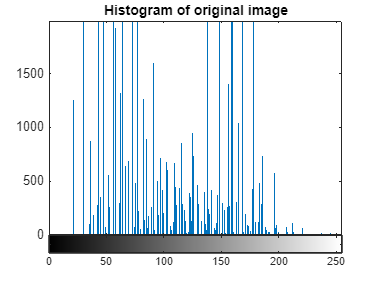


[counts, x] = imhist(I,256);
figure
imhist(I);
title('Histogram of original image')

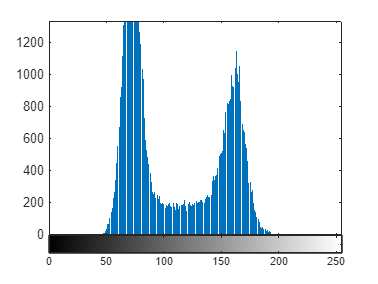

T = otsuthresh(counts);
I_otsu_bin = imbinarize(I, T);

I_f = uint8(mean_filt(I, 10));
[counts_f, x] = imhist(I_f,256);
figure
imhist(I_f);

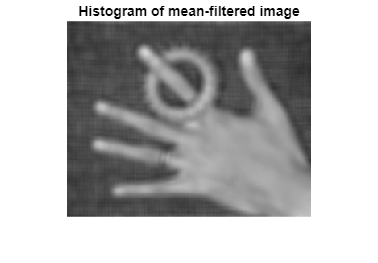

figure
imshow(I_f);
title('Histogram of mean-filtered image')

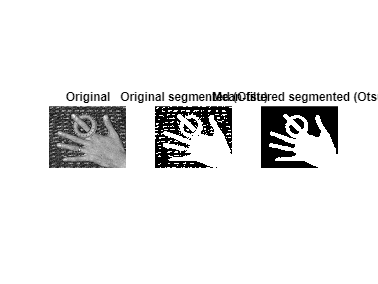

T_f = otsuthresh(counts_f);
I_f_otsu_bin = imbinarize(I_f, T_f);

figure
subplot(1,3,1)
imshow(I)
title('Original')
subplot(1,3,2)
imshow(I_otsu_bin)
title('Original segmented (Otsu)')
subplot(1,3,3)
imshow(I_f_otsu_bin)
title('Mean-filtered segmented (Otsu)')
axis off;



function I_f = mean_filt(I, w_size)
    [rows, cols] = size(I);
    padding = floor(w_size / 2);
    I_f = zeros(rows, cols);
    I_padded = padarray(I, [padding, padding], 'replicate', 'both');
    for i = 1:rows
        for j = 1:cols
            window = I_padded(i:i+w_size-1, j:j+w_size-1);
            window_mean = sum(window, 'all') / w_size^2;
            I_f(i, j) = window_mean;
        end
    end
end